# Derivatives with FFT

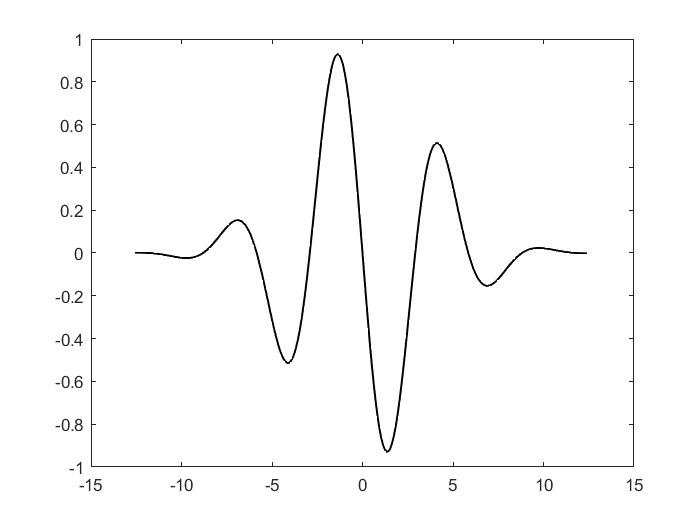

clear;clc;
dx = 0.1;
L = 8*pi;
x = -L/2:dx:L/2-dx;
f = cos(x).*exp(-x.^2/25);
df = -(sin(x).*exp(-x.^2/25)+cos(x).*exp(-x.^2/25).*(2*x)/25);
figure(1);
plot(x,df,'k','LineWidth',1);

N = length(x);

## Forward Difference Derivative

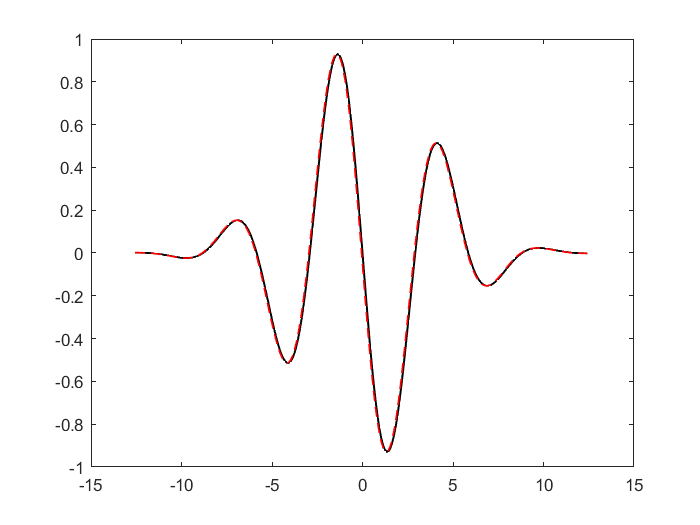

dfFD = zeros(N,1);
for j=1:N-1
    dfFD(j) = (f(j+1)-f(j))/dx;
end
dfFD(N) = dfFD(N-1);

hold on;
plot(x,dfFD,'r--','LineWidth',1);

## Spectral Derivative

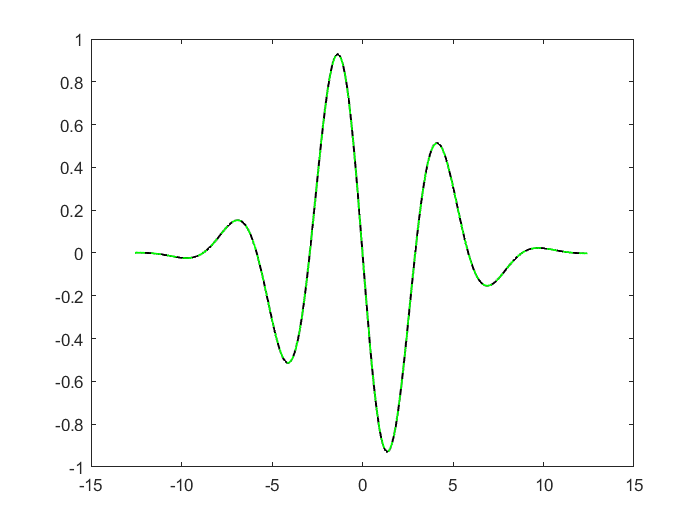

fk = fft(f);
w = (2*pi/L)*(-N/2:N/2-1); % Range of frequencies considered by matlab fft function
w = fftshift(w); % This makes the order aligned with that of matlab
dfk = 1i*w.*fk;
dfSD = real(ifft(dfk));
figure(2);
plot(x,df,'k','LineWidth',1);
hold on;
plot(x,dfSD,'g--','LineWidth',1);

## Benchmark

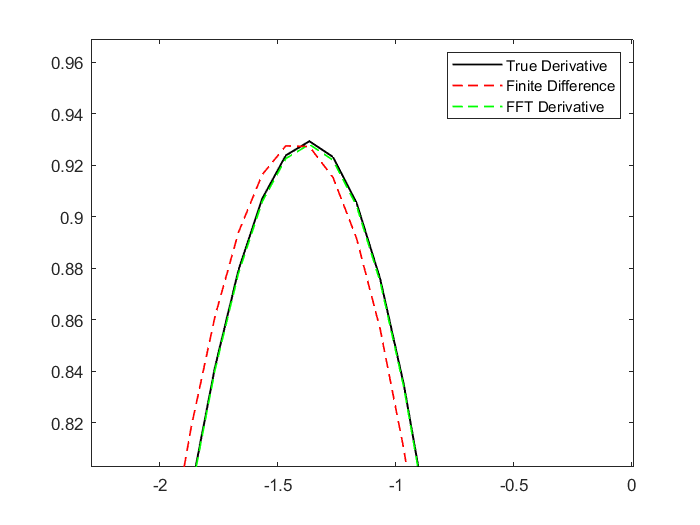

figure(3);
plot(x,df,'k','LineWidth',1);
hold on;
plot(x,dfFD,'r--','LineWidth',1);
plot(x,dfSD,'g--','LineWidth',1);
legend('True Derivative', 'Finite Difference', 'FFT Derivative');